# Example of Power Spectral Density Calculation

## By Tara, Katrina, and Justin

Our goal is to compute the periodogram manually using the FFT of the signal. We will be exploring an example of to compute the periodogram based on an even length, real valued signal.

First we begin with a sampling frequency of 1 kHz and the time axis of 1 second

fs = 1000;
t = 0:1/fs:1-1/fs;

Then we generate a sinusoidal signal at 100 Hz with random noise

x = cos(2*pi*100*t) + randn(size(t));

Below we are performing the FFT of the signal, and we keep only the positive frequencies. For our energy spectrum density analysis we take the square of the FFT and put it over N.

N = length(x);
xdft = fft(x);
xdft = xdft(1:N/2+1);
esdx = (1/(N)) * abs(xdft).^2;
esdx(2:end-1) = 2*esdx(2:end-1);
freq = 0:fs/length(x):fs/2;

Here we plot the periodogram in decibels

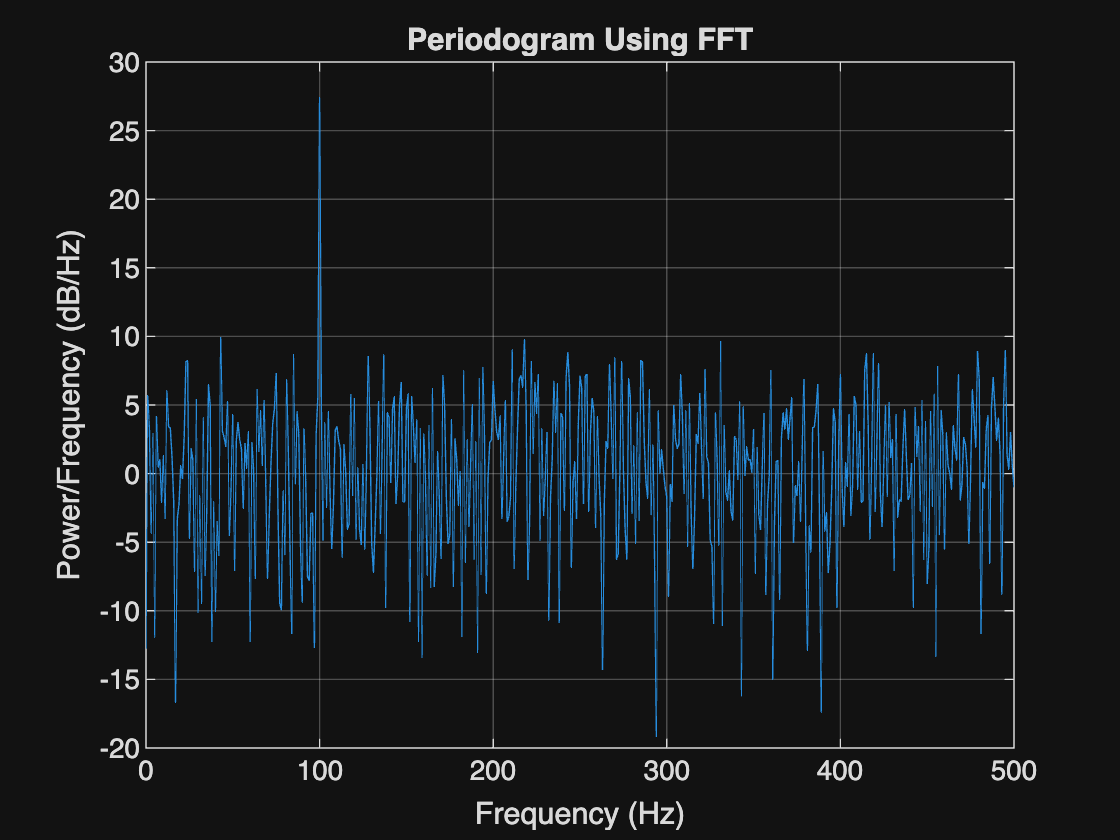

plot(freq,pow2db(esdx))
grid on
title("Periodogram Using FFT")
xlabel("Frequency (Hz)")
ylabel("Power/Frequency (dB/Hz)")

We plot the periodogram from the MATLAB function to show for comparision, to show they look similar. This function however is calculating for a PSD estimation which assumes an infinite signal and averages with the sampling frequency as well.

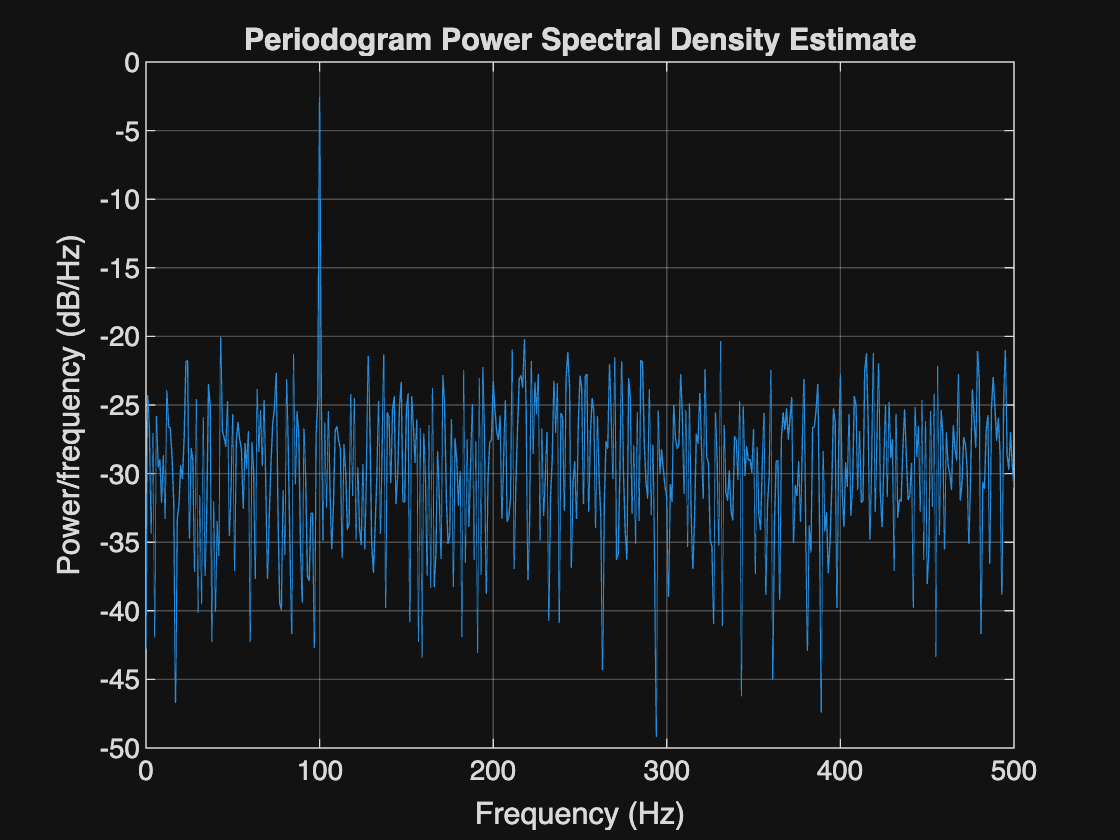

periodogram(x,rectwin(N),N,fs)

We multiply it with the sampling rate to receive the esd and calculate the error which is low

[psd, f] = periodogram(x, rectwin(N), N, fs);
esd_x = psd * fs;

mxerr = max(esdx'-esd_x)

mxerr = 2.6645e-15

Now we want to calculate the threshold for the ESD energy and filter the frequency based on this threshold

% Threshold (e.g., keep frequencies with ESD > 10% of max)
threshold = 0.1 * max(esdx);
xdft_filtered = xdft;
xdft_filtered(esdx < threshold) = 0;  % Zero out small-energy frequencies

% Reconstruct the time-domain signal
x_filtered = ifft([xdft_filtered, conj(xdft_filtered(end-1:-1:2))], 'symmetric');

After plotting we can see we have effectively filtered out the noise from the signal based on the ESD estimation

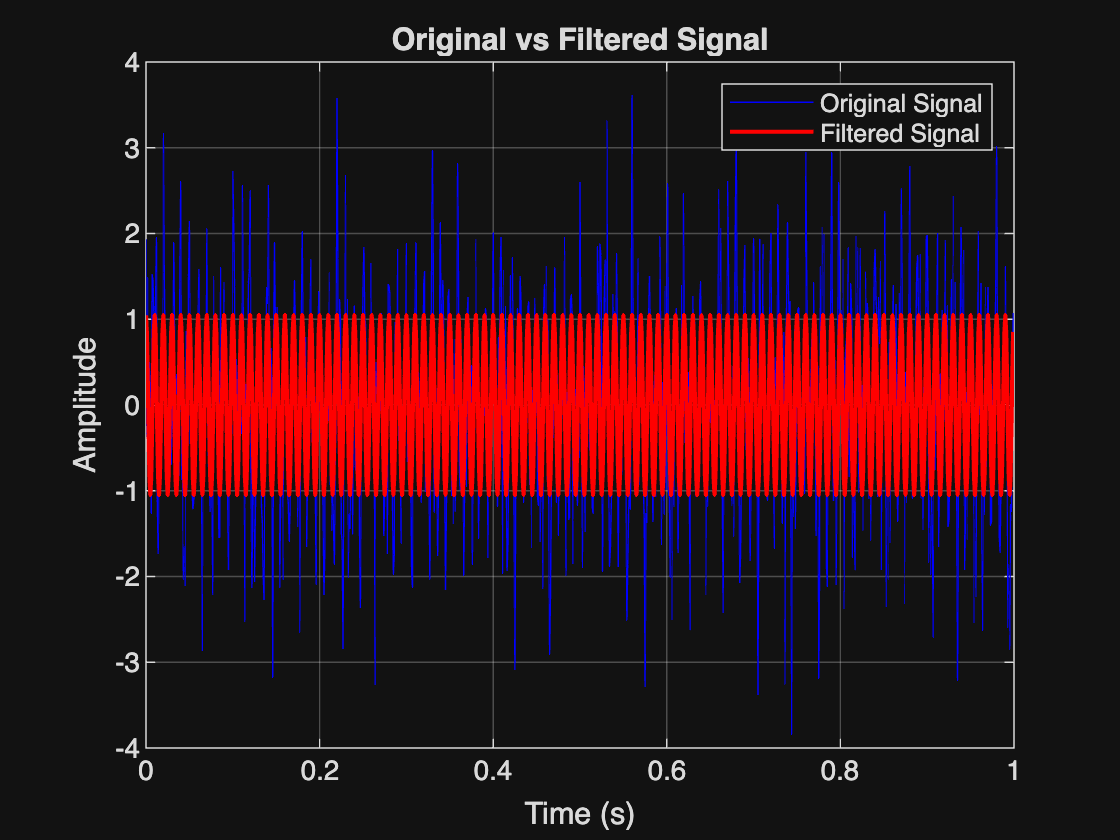

figure;
plot(t, x, 'b', 'DisplayName', 'Original Signal'); % Blue line
hold on;
plot(t, x_filtered, 'r', 'LineWidth', 1.5, 'DisplayName', 'Filtered Signal'); % Red line
hold off;

grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Original vs Filtered Signal');
legend;  % Shows the labels